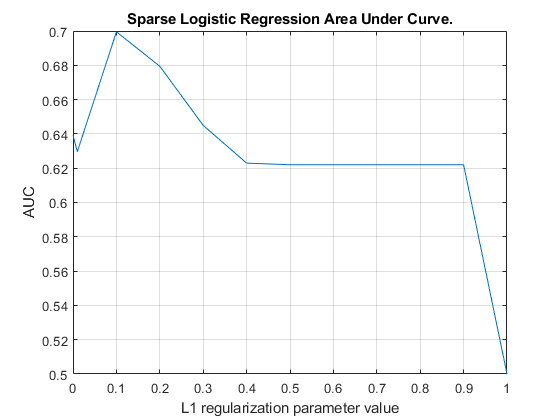

opts.rFlag = 1; % range of par within [0, 1].
opts.tol = 1e-6; % optimization precision
opts.tFlag = 4; % termination options.
opts.maxIter = 5000; % maximum iterations.

par  = [0, 0.01, 0.1, 0.2, 0.3, 0.4, 0.5, 0.6, 0.7, 0.8, 0.9, 1];

load("ad_data.mat")
load("feature_name.mat")

AUC_storage = zeros(length(par), 1);
features = zeros(length(par), 1);

for i=1:length(par)
    [w, c] = logistic_l1_train(X_train, y_train, par(i));

    [X, Y, T, AUC] = perfcurve(y_test, X_test*w + c, 1);
    
    features(i) = sum(w(:) ~= 0);
    AUC_storage(i) = AUC;
end

plot(par, AUC_storage)
title("Sparse Logistic Regression Area Under Curve.");
xlabel("L1 regularization parameter value")
ylabel("AUC")
grid on

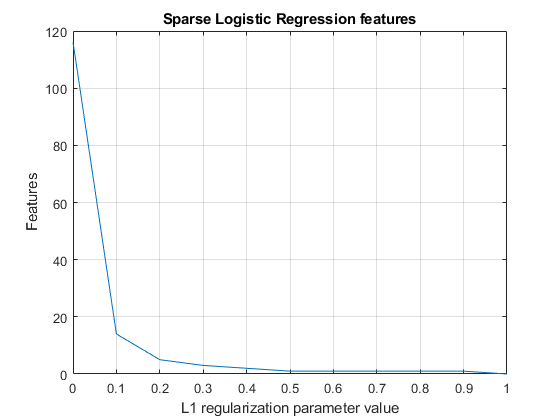


plot(par, features);
title("Sparse Logistic Regression features");
xlabel("L1 regularization parameter value")
ylabel("Features")
grid on

function [w, c] = logistic_l1_train(data, labels, par)
% OUTPUT w is equivalent to the first d dimension of weights in logistic train
% c is the bias term, equivalent to the last dimension in weights in logistic train.
% Specify the options (use without modification).
opts.rFlag = 1; % range of par within [0, 1].
opts.tol = 1e-6; % optimization precision
opts.tFlag = 4; % termination options.
opts.maxIter = 5000; % maximum iterations

[w, c] = LogisticR(data, labels, par, opts);
end
